## Resitting exam 04-07-2023

### Problem 3												

Consider the stationary 2D heat equation $-k_{c}\Delta T = f$ on the square $\Omega = [0,1]\times [0,1]$. The thermal conductivity is $k_{c} = 2.0 W/(m \degree\mathrm{C})$ The temperature is fixed at $T=15.0\degree\mathrm{C}$ at the top edge and $T = -10.0\degree\mathrm{C}$ at the bottom edge. On the side edges there is convection: the media in contact with the left edge is at $T_{\infty} = 100\degree\mathrm{C}$and the convection coefficient is $\beta = 30.0$ whereas the media in contact with the right edge is at $T_{\infty} = 55.0\degree\mathrm{C}$ and convection coefficient is $\beta = 45.0$ 					

Using the mesh defined in the file `mesh8x8Quad.m`, and assuming that there is a constant heat generation $f = 150.0 \mathrm{W}/\mathrm{m}^{3}$ at the region$A$made up by the union of the elements that have all their nodes at, or below the diagonal $y = x$ (region dashed in Yellow at the Figure below), carry out the corresponding FEM analysis and answer the following questions.

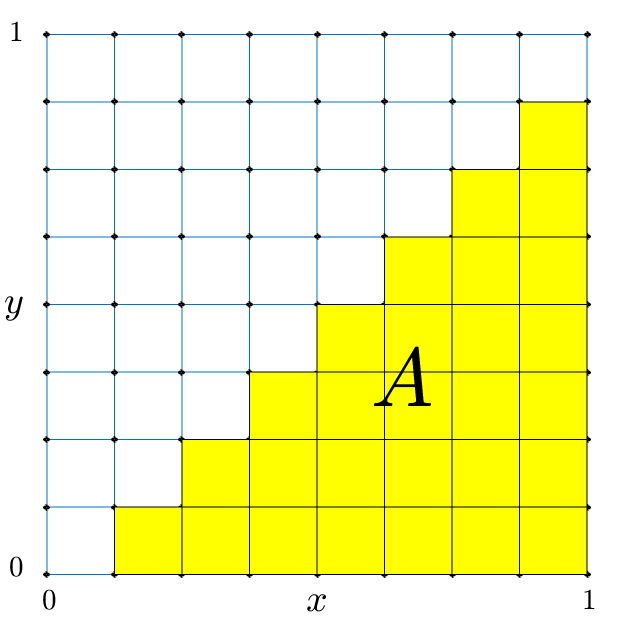

(a) (4 points) The maximum nodal temperature on the region $B:= \Omega\setminus A$ (in $\degree\mathrm{C}$) is 

**Remark**. Notr that nodes in region $B$ are those that do **not** belong to any of the elements tiling the region $A$.				

- `9.2752e+01`

- `8.7255e+01`

- Leave it empty (no penalty) 

- `9.1128e+01`

- `8.8760e+01`$\surd$

- `9.1025e+01` 

*Hint.* The temperature in node $81$is `3.1243e+01`$\degree\text{C}$.

**Solution.** 

clearvars;
close all;

f = 150.0;                   % (W/m^3) Heat generation at region A
indNodHint = 81;             % We give the temperature at node indNodHint

meshFile = 'mesh8x8Quad';    % (.m) file with the mesh's nodes and elements 
kc = 2.0;                    % Thermal conductivity
tempTop = 15.0;              % Temperature at the top boundary
tempBot = -10.0;             % Temperature at the bottom boundary
TinfLeft = 100.0;            % Bulk temperature at left edge
betaLeft = 30.0;             % Convection coefficient at left edge 
TinfRight = 55.0;            % Bulk temperature at right edge
betaRight = 45.0;            % Convection coefficient at right edge

%Point for interpolated temperature 
interpPointP = [0.31250, 0.31250];

%Point for interpolated temperature (1D interpolation & nodes on diagonal)
interpPointR = [0.81250,0.81250];

showPlt = 'Y';               % Show plots: yes

eval(meshFile);
numNod= size(nodes,1);
numElem= size(elem,1);

indNodTop = find(nodes(:,2) > 0.99);
indNodBot = find(nodes(:,2) < 0.01);
indNodLeft = find(nodes(:,1) < 0.01);
indNodRight = find(nodes(:,1) > 0.99);
indNodDiag = find( abs(nodes(:,1)-nodes(:,2)) < 0.01 );

% Define Coefficients vector of the model equation
% In this case we use the Poisson coefficients defined in the problem above
a11 = kc;
a12=0.0;
a21=a12;
a22=a11;
a00=0.0;
coeff=[a11,a12,a21,a22,a00,0];

K=zeros(numNod);
F=zeros(numNod,1);
Q=zeros(numNod,1);

elemHeatGen = [];

for e=1:numElem
    %
    % x and y coordinates of the nodes of the element
    %
    x=nodes(elem(e,:),1); y=nodes(elem(e,:),2);

    if (min(y) < min(x) - 0.01) % Is element e (strictly) below the diagonal?
        elemHeatGen=[elemHeatGen,e];
        coeff(6) = f;
    else
        coeff(6) = 0.0;
    end  

    [Ke,Fe]=bilinearQuadElement(coeff,nodes,elem,e);

    %
    % Assemble the elements
    %
    rows=[elem(e,1); elem(e,2); elem(e,3); elem(e,4)];
    colums= rows;
    K(rows,colums)=K(rows,colums)+Ke; %assembly
    if (coeff(6) ~= 0)
        F(rows)=F(rows)+Fe;
    end
end %end for elements

% We save a copy of the initial F array for the postprocess step
Kini= K;
Fini= F;

%Booundary Conditions
fixedNodes= [indNodBot', indNodTop'];            %fixed Nodes (global numbering)
freeNodes= setdiff(1:numNod,fixedNodes);   %free Nodes (global numbering)

%------------- Convetion BC
indCV=indNodLeft';
[K,Q]=applyConvQuad(indCV,betaLeft,TinfLeft,K,Q,nodes,elem);
indCV=indNodRight';
[K,Q]=applyConvQuad(indCV,betaRight,TinfRight,K,Q,nodes,elem);

% ------------ Essential BC
u=zeros(numNod,1); %initialize u vector
u(indNodTop)=tempTop;
u(indNodBot)=tempBot;
Fm=F(freeNodes)-K(freeNodes,fixedNodes)*u(fixedNodes);%here u can be 
                                                      %different from zero 
                                                      %only for fixed nodes
%Reduced system
Km=K(freeNodes,freeNodes);
Fm=Fm+Q(freeNodes);

%Compute the solution
%solve the System
format short e; %just to a better view of the numbers
um=Km\Fm;
u(freeNodes)=um;

%PostProcess: Compute secondary variables table, and plot results
Q=Kini*u-Fini;

% Table the solutions
sz = [numNod, 5];
varTypes = ["int32", "double", "double", "double", "double"];
varNames = ["Num.Nod", "X", "Y", "T", "Q"];

sols = table('Size', sz,...
    'VariableTypes', varTypes,...
    'VariableNames', varNames);

sols(:,1) = table((1:numNod)'); 
sols(:,2) = table(nodes(:,1));
sols(:,3) = table(nodes(:,2));
sols(:,4) = table(u);
sols(:,5) = table(Q);
format short e
format compact
sols

sols = 81×5 table
    Num.Nod        X             Y              T              Q     
    _______    __________    __________    ___________    ___________
       1       0.0000e+00    0.0000e+00    -1.0000e+01    -5.6098e+01
       2       1.0000e+00    0.0000e+00    -1.0000e+01    -3.8945e+01
       3       1.2500e-01    0.0000e+00    -1.0000e+01    -1.0375e+02
       4       2.5000e-01    0.0000e+00    -1.0000e+01    -5.9153e+01
       5       3.7500e-01    0.0000e+00    -1.0000e+01    -4.4400e+01
       6       5.0000e-01    0.0000e+00    -1.0000e+01    -3.8591e+01
       7       6.2500e-01    0.0000e+00    -1.0000e+01    -3.8512e+01
       8       7.5000e-01    0.0000e+00    -1.0000e+01    -4.5185e+01
       9       8.7500e-01    0.0000e+00    -1.0000e+01    -7.2841e+01
      10       1.0000e+00    1.0000e+00   

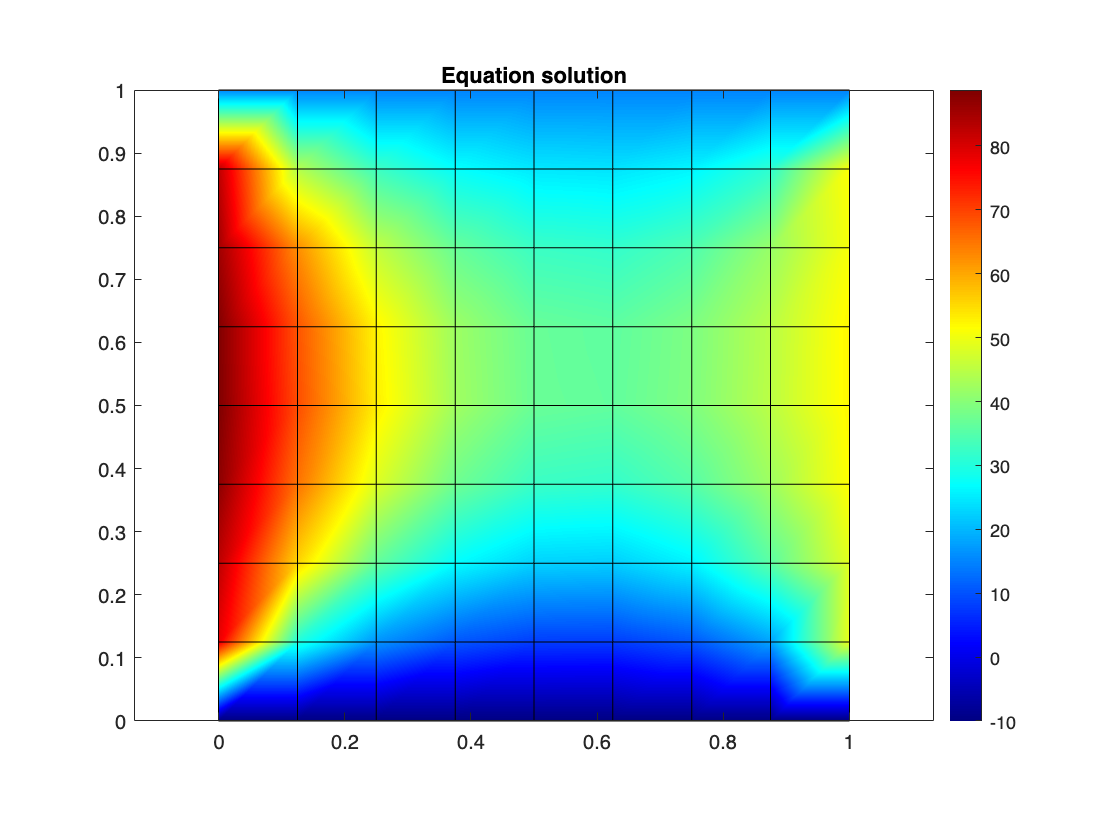


%Plot the results
titol='Equation solution';
colorScale='jet';
if showPlt == 'y' || showPlt == 'Y'
    plotContourSolution(nodes,elem,u,titol,colorScale);
end

% Part (a)
% Compute the maximum temperature at the nodes of region B
nodesHeatGen = elem(elemHeatGen, :);
nodesHeatGen = nodesHeatGen(:);
nodesHeatGen = unique(nodesHeatGen);
nodesWithoutHeatGen = setdiff(1:numNod, nodesHeatGen);
[maxTempB, idx] = max(u(nodesWithoutHeatGen));
nodMaxTempB = nodesWithoutHeatGen(idx); 

fprintf(['\n',...
    '(a) Temp Max. in B is T= %.4eºC, at node %3d\n',...
    '    Hint. The temperature at node %d is, T= %.4e%cC\n'],...
    maxTempB,nodMaxTempB,indNodHint,u(indNodHint),char(176))


(a) Temp Max. in B is T= 8.8760e+01ºC, at node  29
    Hint. The temperature at node 81 is, T= 3.1243e+01°C


(b) (3 points)  The interpolated temperature at point $P = (0.31250, 0.31250)$ is (in$\degree\mathrm{C}$)	

- `3.7232e+01`$\surd$

- `3.2725e+01`

- `3.3244e+01`

- `3.5946e+01`

- `3.2877e+01`

- Leave it empty (no penalty) 

**Solution.** 									

% Part (b)
%Compute the interpolated temperature at point P
for e=1:numElem
    nods = elem(e,:);
    vertexs= nodes(nods,:);
    [alphas,isInside] = baryCoordQuad(vertexs,interpPointP);
    if (isInside > 0)
        %numElemPointP = e;
        %indNodElemPointP = elem(numElemPointP,:);
        interpTempPointP = alphas * u(nods);
        fprintf(['\n',...
          '(b) Point P = (%.5f, %.5f) belongs to element number: %d\n',...
          '    Indexs of the nodes of elem %d: %d, %d, %d, %d\n', ...
          '    Interpolated temperature at point P, T= %.4e%cC\n'],...
          interpPointP,e,e,nods,interpTempPointP,char(176))
        break;
    end
end


(b) Point P = (0.31250, 0.31250) belongs to element number: 19
    Indexs of the nodes of elem 19: 41, 48, 49, 42
    Interpolated temperature at point P, T= 3.7232e+01°C


(c) (3 points) Now, consider just the nodes at the diagonal $y = x$. Using the temperatures $T_{i}$, $i = 1,\dots,n_{d}$, at **all** these nodes, and their corresponding abscissas $x_{i}$ $i=1,\dots,n_{d}$, the temperature’s approximation (in $\degree\text{C}$) at the point $R= (0.81250, 0.81250)$ given by $1$D-interpolation polynomial (computed, recall, taking all the nodes at the diagonal) is found to be 					

- `3.4212e+01`

- `3.5752e+01`

- `3.3239e+01`$\surd$

- `3.6042e+01`

- Leave it empty (no penalty)

- `2.8327e+01` 

**Solution.** 

% Part (c)
xx = nodes(indNodDiag,1);
numNodsOnDiag = length(xx);
tempDiag = u(indNodDiag);
cf = polyfit(xx, tempDiag, numNodsOnDiag - 1);

interpTempPointR = polyval(cf, interpPointR(1,1));
averagedTempDiag = sum(tempDiag)/numNodsOnDiag;

fprintf(['\n',...
    '(c) Interpolated temperature at point R = (%.5f, %.5f)\n', ...
    '    using nodes at the diagonal & 1D interpolation T = %.4e%cC\n', ...
    '    Hint. Averged temperature of the nodes at the diagonal, <T> = %.4e%cC\n'], ...
    interpPointR,interpTempPointR,char(176),averagedTempDiag,char(176))


(c) Interpolated temperature at point R = (0.81250, 0.81250)
    using nodes at the diagonal & 1D interpolation T = 3.3239e+01°C
    Hint. Averged temperature of the nodes at the diagonal, <T> = 2.7500e+01°C


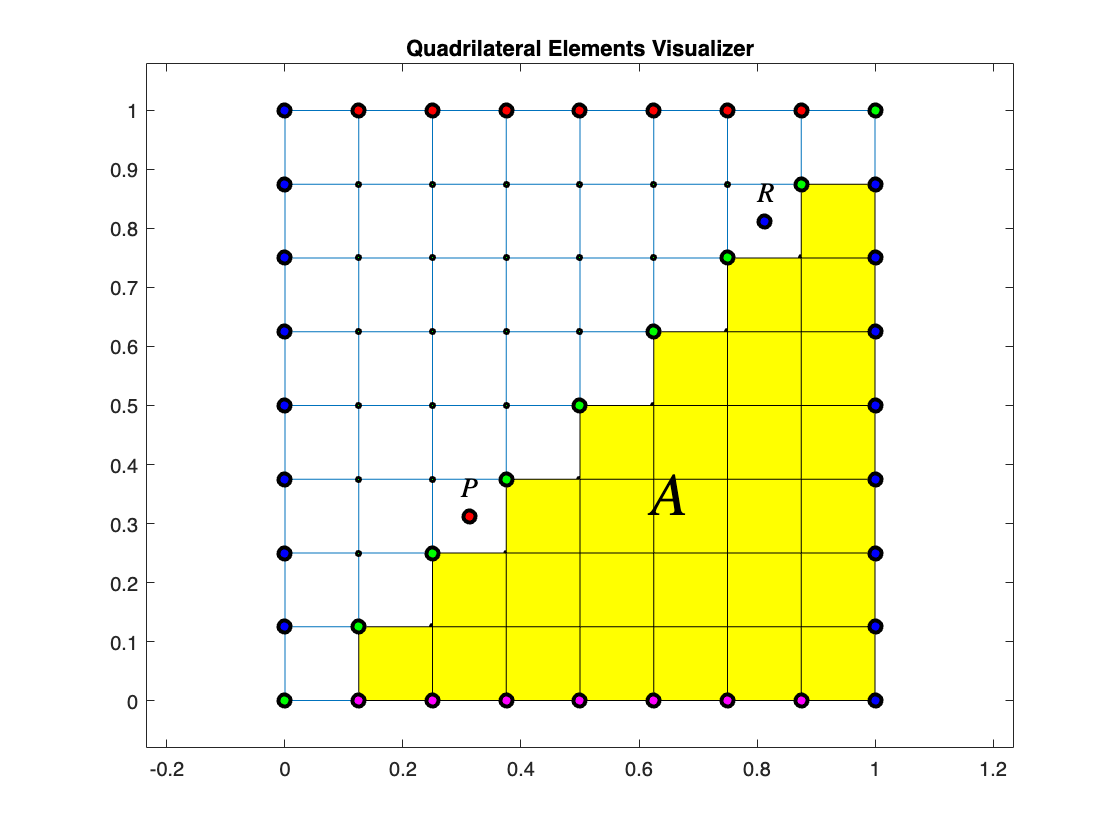

%Plot the domain and the points P and R
if showPlt == 'y' || showPlt == 'Y'
    %figure
    numbering = 0;
    %plotElements(nodes, elem, numbering);
    plotElementsOld(nodes, elem, numbering);
    hold on

    numElemHeatGen = length(elemHeatGen);
    X = nodes(elem(elemHeatGen,:)',1); X=reshape(X,4,numElemHeatGen);
    Y = nodes(elem(elemHeatGen,:)',2); Y=reshape(Y,4,numElemHeatGen);
    fill(X,Y,'yellow')

    plot(nodes(indNodTop,1),nodes(indNodTop,2), ...
        'ok','lineWidth',2,'markerFaceColor','red','markerSize',6)
    plot(nodes(indNodBot,1),nodes(indNodBot,2), ...
        'ok','lineWidth',2,'markerFaceColor','magenta','markerSize',6)
    plot(nodes(indNodLeft,1),nodes(indNodLeft,2), ...
        'ok','lineWidth',2,'markerFaceColor','blue','markerSize',6)
    plot(nodes(indNodRight,1),nodes(indNodRight,2), ...
        'ok','lineWidth',2,'markerFaceColor','blue','markerSize',6)     
    plot(nodes(indNodDiag,1),nodes(indNodDiag,2), ...
        'ok','lineWidth',2,'markerFaceColor','green','markerSize',6)

    plot(interpPointP(1,1),interpPointP(1,2), ...
     'ok','lineWidth',2,'markerFaceColor','red','markerSize',6)
    text(interpPointP(1,1)-0.02, interpPointP(1,2)+0.05, '$P$',...
     'interpreter','LaTeX','fontSize', 14)

    plot(interpPointR(1,1),interpPointR(1,2), ...
        'ok','lineWidth',2,'markerFaceColor','blue','markerSize',6)
    text(interpPointR(1,1)-0.02, interpPointR(1,2)+0.05, '$R$',...
        'interpreter','LaTeX','fontSize', 14)
    text(0.6, 0.35, '$A$', 'Interpreter', 'LaTeX', 'FontSize', 30, ...
    'color', 'black')
    hold off 
end